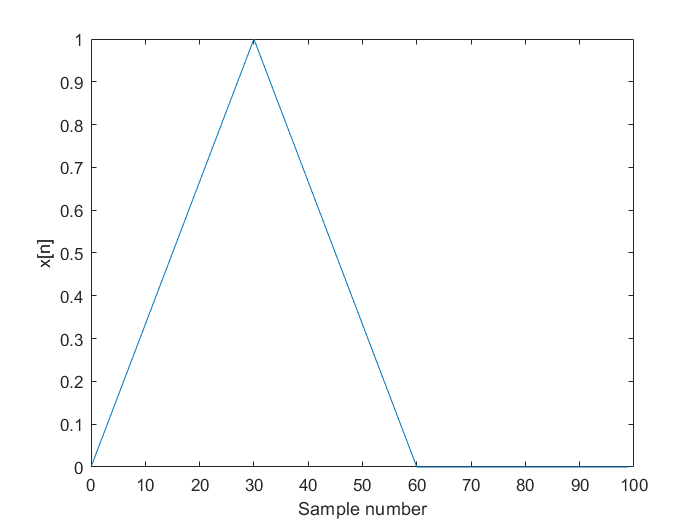

clear all;
close all;
clc;

x = 0:99;
y = (30 - abs(x-30)) / 30;
y(61:100) = 0;
plot(x,y);
xlabel('Sample number');
ylabel('x[n]')

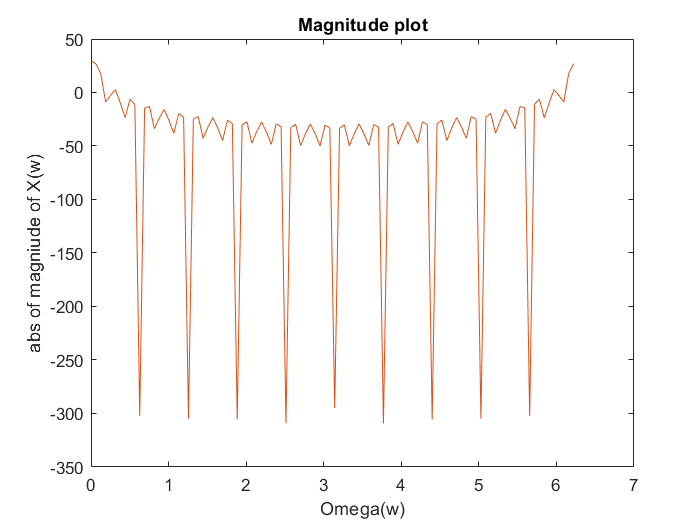


% Plot the fft of triangle directly.
L = length(y);
Xw = fft(y);
% Xw_half_frequency = Xw(1:L/2);
Omega = 0:pi/50:99/50*pi;
plot(Omega, mag2db(abs(Xw)));
xlabel('Omega(w)');
ylabel('abs of magniude of X(w)');
title('Magnitude plot');
hold on;

% Plot of the triangle by two parts.
fft_by_two_parts_result = mag2db(abs(fft_by_two_parts(y)));
plot(Omega, fft_by_two_parts_result);
hold off;

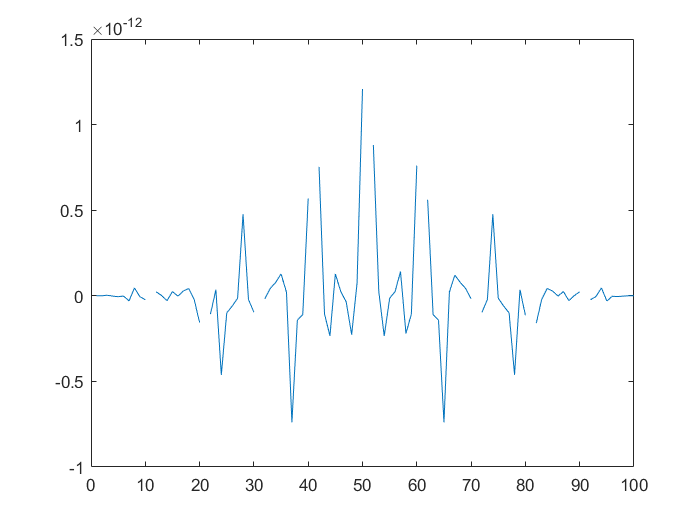

plot(mag2db(abs(Xw)) - fft_by_two_parts_result)

function fft_final =  fft_by_two_parts(x)
y = x;
index_even = 1;
index_odd = 1;
even_part = zeros(1, 50);
odd_part = zeros(1, 50);
for i = 1:2:99
    even_part(index_even) = x(i);
    index_even = index_even + 1;
end
for m = 2:2:100
    odd_part(index_odd) = x(m);
    index_odd = index_odd + 1;
end
k = 0:49;
% exp_array = exp((-j)*2*pi*k / 100) 
fft_even_part_01 = fft(even_part);
fft_odd_part_01 = exp((-j)*2*pi*k / 100)  .* fft(odd_part);
k = 50:99;
fft_even_part_02 = fft(even_part);
fft_odd_part_02 = exp((-j)*2*pi*k / 100)  .* fft(odd_part);

fft_final = [fft_even_part_01, fft_even_part_02] + [fft_odd_part_01, fft_odd_part_02];
end
